clear;clc;
%定义变量
format long
EV_position1=rand(2,25).*8;
EV_position2=7+rand(2,25).*8;
% 生成第一行的随机数组，范围在15到20之间
first_row = 7 + (22-14) * rand(1, 25);
% 生成第二行的随机数组，范围在0到5之间
second_row = 0 + (8-0) * rand(1, 25);
% 将两行数组合并成一个 2x25 的数组
EV_position3 = [first_row; second_row];
% 生成第一行的随机数组，范围在15到20之间
first_row = 0 + (22-14) * rand(1, 25);
% 生成第二行的随机数组，范围在0到5之间
second_row = 7 + (8-0) * rand(1, 25);
% 将两行数组合并成一个 2x25 的数组
EV_position4 = [first_row; second_row];
EV_position=[ EV_position1,EV_position4,EV_position3,EV_position2];%电动汽车的位置
EV_SOC_0=rand(1,100).*0.5+0.2;%电动汽车的SOC初始值，在0.2到0.9之间
CS_position=[0 0 15 15;0 15 0 15];%充电站的位置
DT=1:45;
B=[0.2,5,1];
eta_PV = 0.4; % 光伏效率
P_mpp = 500; % 光伏最大功率点功率，假设为20
% 变量 光照强度矩阵，假设随正态分布变化
Irr = zeros(length(CS_position), length(DT)); 
for i=1:length(CS_position)
rng(0);
% 定义正态分布的均值和标准差
mu = 20; % 均值
sigma = 50; % 标准差
% 生成10个正态分布随机数
Irr(i,:) = 50*normpdf(1: length(DT),mu, sigma);
end
f_temp = rand(length(CS_position), length(DT)); % 变量 温度函数矩阵，假设为随机值
for i=1:length(CS_position)
rng(0);
% 定义正态分布的均值和标准差
mu = 20; % 均值
sigma = 100; % 标准差
% 生成10个正态分布随机数
f_temp(i,:) = 50*normpdf(1: length(DT),mu, sigma);
end
% 计算光伏注入功率 P_PV
n=[30,50,50,90];
P_PV = zeros(length(CS_position), length(DT));
for s = 1:length(CS_position)
    for t = 1:length(DT)
        P_PV(s, t) =n(s)* eta_PV * P_mpp * Irr(s, t) * f_temp(s, t);
    end
end
fobj=@(x) -optimization(x,EV_position,CS_position,EV_SOC_0,P_PV,B);
N=100;
Max_iteration=20;
lb = 0; % 变量下界
ub = 10.9; % 变量上界
dim=4;
% %HEOA算法
% fobj=@(x) -optimization(x,EV_position,CS_position,EV_SOC_0,P_PV,B);
% [~, Best_pos, Best_score, ~, ~,~] = HEOA(N,Max_iteration,lb,ub,dim,fobj);
% incentives3=Best_pos;
% income=-Best_score;
incentives3=[5.31309806929290,	5.61563847037892,	5.52100680127222,	5.96439148811025];
%incentives3=[4.5,4.5,4.5,4.5]
[fitness,EV_SOC_F,SOC_time,P_EV,u_s,income,sigma,P_dso] = optimization(incentives3,EV_position,CS_position,EV_SOC_0,P_PV,B);  

Constraint 7: 1
Constraint 8: 1


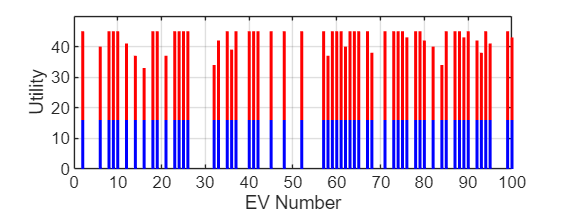

 figtime(SOC_time);

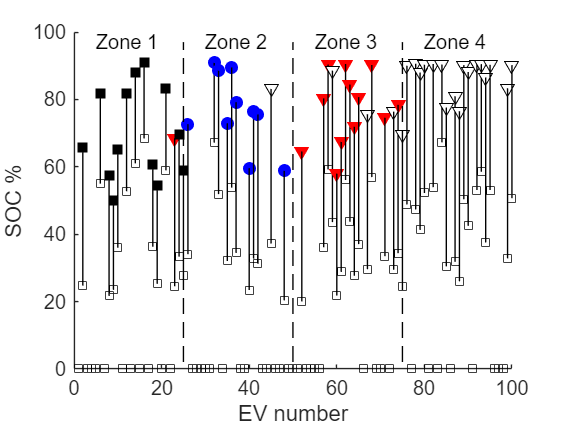

figure('visible', 'off');
figtime(SOC_time);
saveas(gcf, 'C:\Users\12442\Documents\GitHub\EV-charge\EV_Charge\EV_Charge/incentive_SOC_time.png');
figure('visible', 'off');
figsoc(EV_SOC_0,EV_SOC_F,u_s);
saveas(gcf, 'C:\Users\12442\Documents\GitHub\EV-charge\EV_Charge\EV_Charge/incentive_SOC.png');

figure('visible', 'off');
Figpower(P_EV);
saveas(gcf, 'C:\Users\12442\Documents\GitHub\EV-charge\EV_Charge\EV_Charge/incentive_P_EV.png');
figure('visible', 'off');
Figpower(P_PV);
saveas(gcf, 'C:\Users\12442\Documents\GitHub\EV-charge\EV_Charge\EV_Charge/incentive_P_PV.png');
 figsoc(EV_SOC_0,EV_SOC_F,u_s);

  fprintf('激励1,激励2,激励3');

激励1,激励2,激励3

 for s=1:4
 fprintf(' %0.1f%     ',incentives3(s) );
  end

 5.3 5.6 5.5 6.0

 fprintf('总利润： %0.01f%',income);

总利润： 2640896.6

fprintf('\n');  % 结束进度条
